# Signal Processing Analyzer

## **🎯 ****Why do we need Signal Processing?**

- **Signal processing** is essential because **raw signals are rarely ready to use.** They’re often noisy, complex, or too large to analyze directly. Signal processing helps us make sense of them.

- **การประมวลผลสัญญาณ** มีความจำเป็น เพราะสัญญาณที่ได้จากโลกจริงมักจะยังไม่พร้อมใช้งานทันที — อาจมีสัญญาณรบกวน มีความซับซ้อน หรือมีขนาดข้อมูลใหญ่เกินไปการประมวลผลสัญญาณจะช่วยให้เรา "เข้าใจ" และ "ใช้งาน" ข้อมูลเหล่านี้ได้อย่างมีประสิทธิภาพ

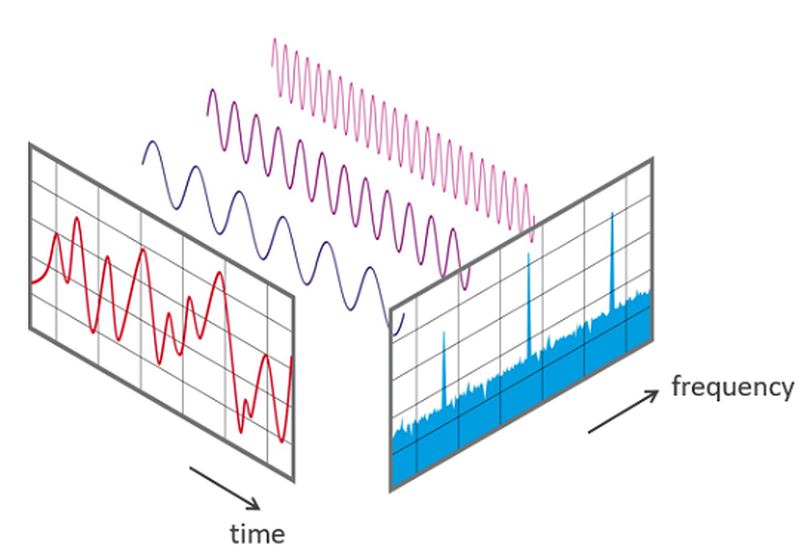

### **Use Cases**

### Today Topics

- Import Data

- Design Filter

- Signal Analyzer

- Generate functions

- Output

## 1. Import data

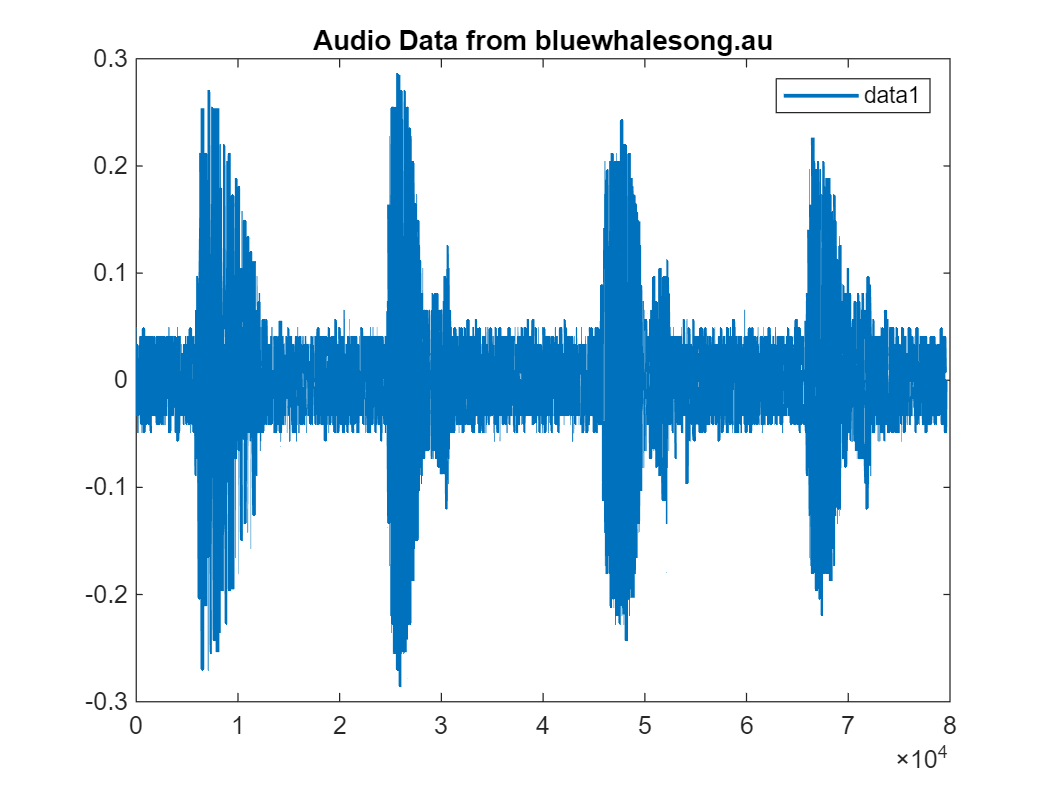

% Import audio
[Whale_Song, fs] = audioread("C:\Users\PattarapolSangaroon\OneDrive - Techsource Systems Pte Ltd\Documents\My_folder\20_Assignment\03_Signal_Processing\bluewhalesong.au");

% Display results
plot(Whale_Song, "LineWidth", 1.5);
title("Audio Data from bluewhalesong.au");
legend;

sound(Whale_Song, fs)

## 2. Customize filter by Design filter task

pspectrum(Whale_Song, fs)

% Design a digital filter
designedFilter = designfilt('lowpassfir', ...
    'PassbandFrequency',800,'StopbandFrequency',850, ...
    'PassbandRipple',1,'StopbandAttenuation',60, ...
    'SampleRate',fs);

% Visualize magnitude and phase responses
freqz(designedFilter,[],fs)

Whale_Song_filter = filter(designedFilter, Whale_Song);
plot(Whale_Song)
hold on
plot(Whale_Song_filter)
hold off
pspectrum(Whale_Song_filter, fs)

sound(Whale_Song_filter, fs)

## 3. Signal Analyzer

####     - Select ROI (Region of Interest)

####     - Preprocessing

        - Noise Reduction

        - Filtering

####     - Time/Frequency Analysis

####     - Export signal/Generate function

%signalAnalyzer

## 4. Generate function

length(Whale_Song);
tx = (0:length(Whale_Song)-1)/fs;

Whale_Song_analyzer = Denoise_and_Bandpass_800_1000(Whale_Song, tx);
plot(Whale_Song_analyzer)
pspectrum(Whale_Song_analyzer, fs)

## 5. Reuse the function --> Export to new audio file

audiowrite("bluewhale_song_filter.wav", Whale_Song_analyzer, fs)